% Sistema de Vector de colores
matriz = [0 60; 1 58; 2 56; 3 54; 4 52; 5 50; 6 48; 7 46; 8 44; 9 42; 10 40];

% Matriz combinada con los datos obtenidos
matriz_combinada = cat(2,tiempo_v.',intensity_v.');

% Se depura la data quedándose sólo con los datos de los colores analizados
matriz_depurada = depura_matrices(matriz_combinada, 100, 425)

matriz_depurada = 6479×2 int32 matrix
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60


matriz_depurada2 = 6479×2 int32 matrix
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58
   101    58


matriz_depurada3 = 6479×2 int32 matrix
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60
   101    60


b = 60

m = -0.0155

y_extremos =    59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9845   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9690   59.9536   59.9536   59.9536   59.9536   59.9536   59.9536   59.9536   59.9536   59.9536   59.9536


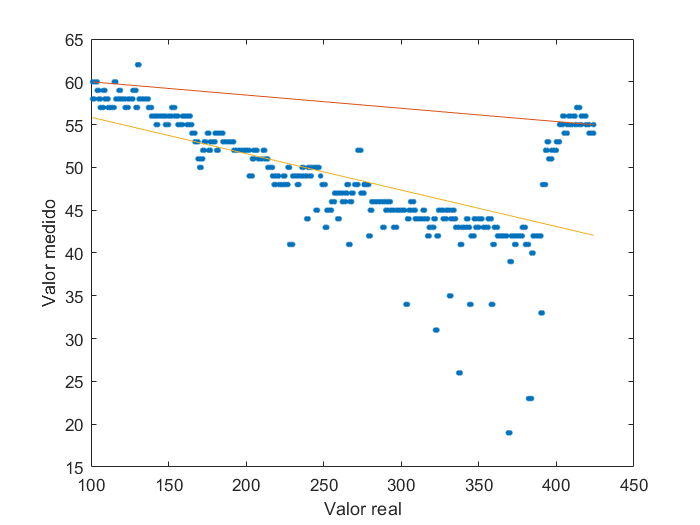

b = 58

m = -0.0124

y_extremos =    57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9876   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9752   57.9628   57.9628   57.9628   57.9628   57.9628   57.9628   57.9628   57.9628   57.9628   57.9628


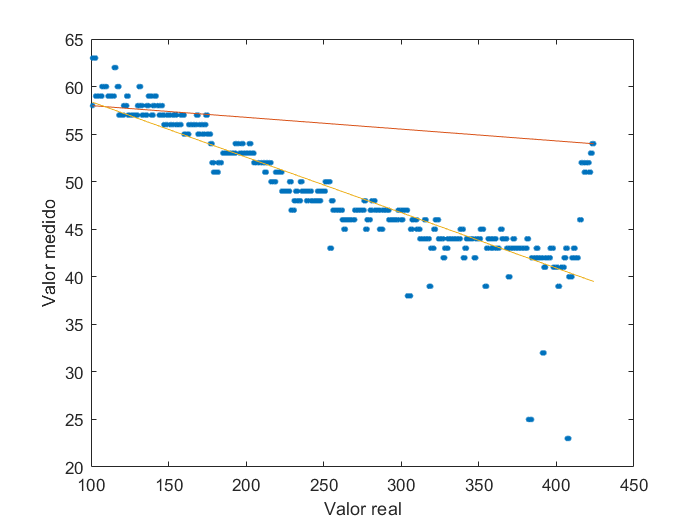

b = 60

m = -0.0557

y_extremos =    59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.9443   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8885   59.8328   59.8328   59.8328   59.8328   59.8328   59.8328   59.8328   59.8328   59.8328   59.8328


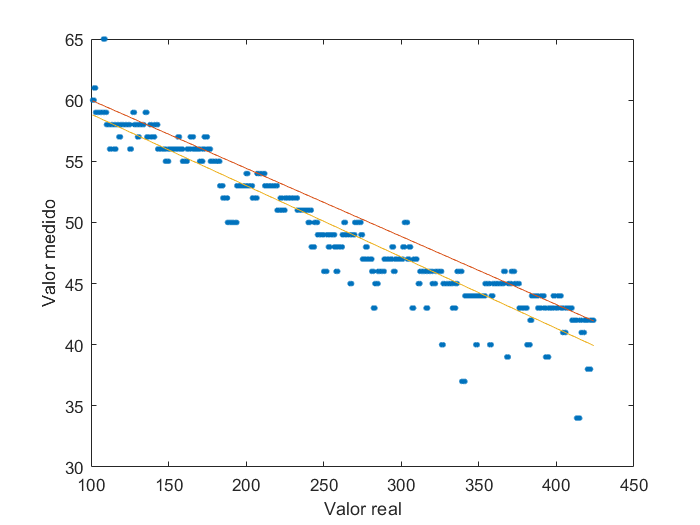

% Curva de Calibración
TestRecta(matriz_depurada(:,1).',matriz_depurada(:,2).', 100)

function matriz_limpia = depura_matrices(matriz, corte_inicio, corte_final)    
    matriz_limpia = [];
    for i = 1: size(matriz,1)
        if matriz(i,1) > corte_inicio && matriz(i,1) < corte_final
            matriz_limpia = [matriz_limpia; matriz(i,:)];
        end
    end
end